# Performance of implementations of loop orderings with inner loop indexed with "P"

## This Live Script

This Live Script helps you visualize the performance of implementations that order the loops so that the "P" loop is the inner-most loop:  Gemm_IJP.c, Gemm_IJ_Dots.c, Gemm_IJ_ddot.c, Gemm_IJ_bli_ddotxv.c, Gemm_JIP.c, Gemm_JI_Dots.c, Gemm_JI_ddot.c, Gemm_JI_bli_ddotxv.c.

To gather the performance data, in the command (terminal) window change the directory to LAFF-On-HPC/Assignments/Week1/C/.  After implementing the various versions,  execute 

       make IJP    (actually, you probably did this one already)

       make IJ_Dots

       make IJ_ddot

       make IJ_bli_ddotxv

       make JIP    (actually, you probably did this one already)

       make JI_Dots

       make JI_ddot

       make JI_bli_ddotxv

This compiles and executes a driver routine (the source of which is in driver.c) that collects accuracy and performance data for the various implementations.  

When completed, various data is in output file 'output_XYZ.m' (for XYZ $$ \in $$ {IJP,IJ_Dots,...}) in the same directory where you found this Live Script (LAFF-On-HPC/Assignments/Week1/C/data/).  This Life Script then creates graphs from that timing data.  Go ahead and click on "Run All".  It executes all the code in the rest of this file.  You will want to look at the graphs this creates.

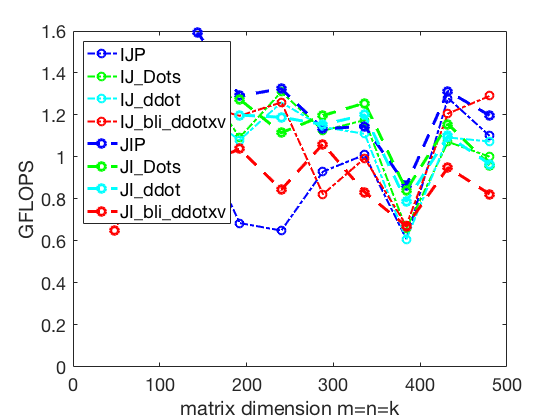

plot_colors = [ 0 0 0; 0 0 1; 0 1 0; 0 1 1; 1 0 0; 1 0 1; 1 1 0; 1 1 1];

% Create figure
figure1 = figure('Name','GFLOPS');

% Create axes, labels, legends.  In future routines for plotting performance, 
% the next few lines will be hidden in the script.
axes2 = axes('Parent',figure1);
hold(axes2,'on');
ylabel( 'GFLOPS', 'FontName', 'Helvetica Neue' );
xlabel( 'matrix dimension m=n=k', 'FontName', 'Helvetica Neue' );
box(axes2,'on');
set( axes2, 'FontName', 'Helvetica Neue', 'FontSize', 18);
             
% Plot time data for IJP  
output_IJP   % load data for IJP ordering
assert( max(abs(data(:,6))) < 1.0e-10, ...
    'Hmmm, better check if there is an accuracy problem');
plot( data(:,1), data(:,5), 'DisplayName', 'IJP', 'MarkerSize', 8, 'LineWidth', 2, ...
      'Marker', 'o', 'LineStyle', '-.', 'Color', plot_colors( 2,: ) );

% Plot time data for IP_Dots  (to plot change "0" to "1")
if ( 1 ) 
  output_IJ_Dots   
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'IJ\_Dots', 'MarkerSize', 8, 'LineWidth', 2, ...
        'Marker', 'o', 'LineStyle', '-.', 'Color', plot_colors( 3,: ) );
end

% Plot time data for IJ_ddot  (to plot change "0" to "1")
if ( 1 ) 
  output_IJ_ddot   
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'IJ\_ddot', 'MarkerSize', 8, 'LineWidth', 2, ...
        'Marker', 'o', 'LineStyle', '-.', 'Color', plot_colors( 4,: ) );
end

% Plot time data for IJ_bli_ddotxv  (to plot change "0" to "1")
if ( 1 ) 
  output_IJ_bli_ddotxv   
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'IJ\_bli\_ddotxv', 'MarkerSize', 8, 'LineWidth', 2, ...
        'Marker', 'o', 'LineStyle', '-.', 'Color', plot_colors( 5,: ) );
end

% Plot time data for JIP  (to plot change "0" to "1")
if ( 1 ) 
  output_JIP  
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'JIP', 'MarkerSize', 8, 'LineWidth', 3, ...
        'Marker', 'o', 'LineStyle', '--', 'Color', plot_colors( 2,: ) );
end

% Plot time data for JI_Dots  (to plot change "0" to "1")
if ( 1 ) 
  output_JI_Dots   
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'JI\_Dots', 'MarkerSize', 8, 'LineWidth', 3, ...
        'Marker', 'o', 'LineStyle', '--', 'Color', plot_colors( 3,: ) );
end

% Plot time data for JI_ddot  (to plot change "0" to "1")
if ( 1 ) 
  output_JI_ddot   
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'JI\_ddot', 'MarkerSize', 8, 'LineWidth', 3, ...
        'Marker', 'o', 'LineStyle', '--', 'Color', plot_colors( 4,: ) );
end

% Plot time data for JI_bli_ddotxv  (to plot change "0" to "1")
if ( 1 ) 
  output_JI_bli_ddotxv  
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'JI\_bli\_ddotxv', 'MarkerSize', 8, 'LineWidth', 3, ...
        'Marker', 'o', 'LineStyle', '--', 'Color', plot_colors( 5,: ) );
end

% Optionally show the reference implementation performance data
if ( 0 )
  plot( data(:,1), data(:,3), 'MarkerSize', 8, 'LineWidth', 1, ...
        'LineStyle', '-', 'DisplayName', 'Ref', 'Color', plot_colors( 1,: ) );
end

% Adjust the x-axis and y-axis range to start at 0
v = axis;                   % extract the current ranges
axis( [ 0 v(2) 0 v(4) ] )   % start the x axis and y axis at zero

% Optionally change the top of the graph to capture the theoretical peak
if ( 0 )
    turbo_clock_rate = 2.6;
    flops_per_cycle = 16;
    peak_gflops = turbo_clock_rate * flops_per_cycle;

    axis( [ 0 v(2) 0 peak_gflops ] )  
end

legend2 = legend( axes2, 'show' );
set( legend2, 'Location', 'northwest', 'FontSize', 18) ;


% Uncomment if you want to create a pdf for the graph
% print( 'Plot_Inner_P.pdf', '-dpdf' );